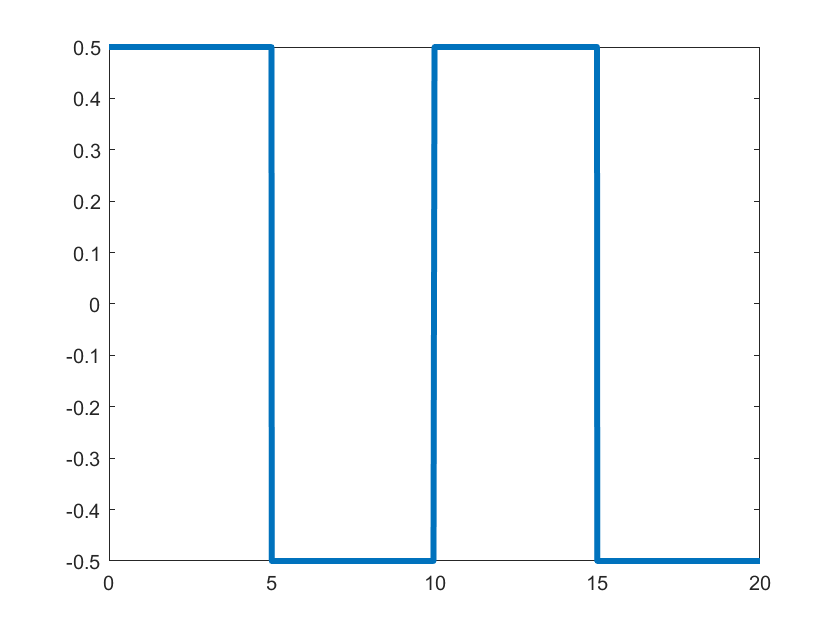

%% 2.8a
[ time_pos , sq_wave , B_unnorm ] = generate_data;
figure;
plot(time_pos, sq_wave, 'LineWidth',3)

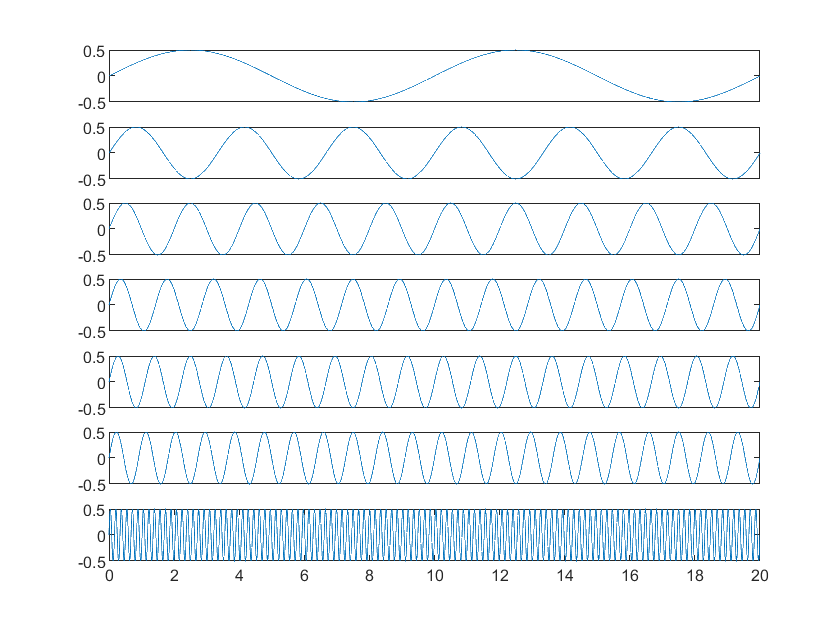

%% 2.8b
figure;
row = [1:6,30];
for i = 1:7
  subplot(7,1,i);
  plot(time_pos, B_unnorm(row(i), :));
  set(gca,'xtick',[])  
end
set(gca,'xtickMode', 'auto')

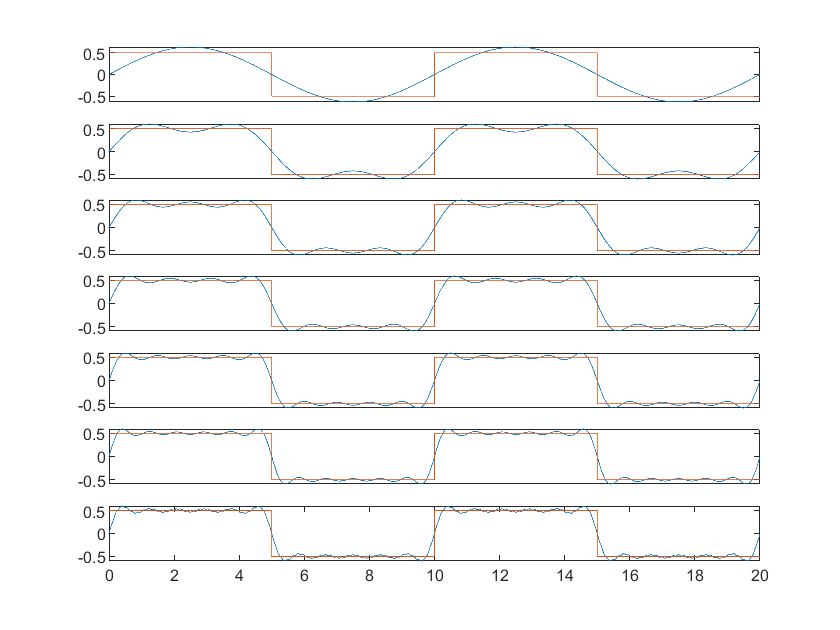

%% 2.8c
B_norm = zeros(size(B_unnorm));
for i = 1:30
    B_norm(i,:) = B_unnorm(i,:)/norm(B_unnorm(i,:));
end

alphas = zeros(30,1);
for i = 1:30
    alphas(i,1) = sum(sq_wave.*B_norm(i,:));
end

[alphasorted,alphasortidx]=sort(alphas, 'descend');
B_norm = B_norm(alphasortidx, :);
B_normT = B_norm';  
figure;
for i = 1:6
  subplot(7,1,i);
  approximation = B_normT(:,1:i)*alphasorted(1:i);
  plot(time_pos, approximation, time_pos, sq_wave)
  set(gca,'xtick',[])  
end
subplot(7,1,7);
approximation = B_normT(:,[1:6,30])*alphasorted([1:6,30]);
plot(time_pos, approximation, time_pos, sq_wave)